### Import the dataset

% "C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\data.csv"
path = strcat("C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\data.csv")

path = "C:\Users\Do Thu An\OneDrive\Desktop\Dynamic Macroeconomics\Problem sets\Dynamic-Macroeconomics\PS1_Code\data.csv"

data = readmatrix(path);

### Exploratory data analysis (EDA)

% Extract actual data columns
actual_T= data(:,1);       % Time
actual_k = data(:,2);      % Empirical capital
actual_i = data(:,3);      % Empirical investment
actual_c = data(:,4);      % Empirical consumption
actual_g = data(:,5);      % Empirical government spending

% Load simulated data
sim_time = (1:length(sim.ksim))'; % Time index
sim_k = sim.ksim;    % Simulated capital
sim_i = sim.isim;    % Simulated investment
sim_c = sim.csim;    % Simulated consumption
sim_g = sim.gsim;    % Simulated government spending

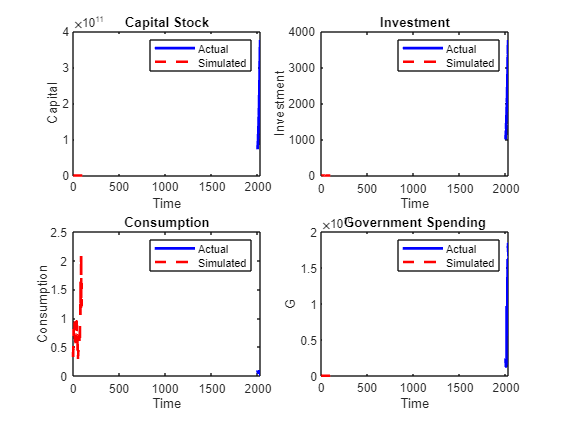

%% Plot Simulated vs Actual Data
figure;

% Capital Stock
subplot(2,2,1);
plot(actual_T, actual_k, 'b', 'LineWidth', 2); hold on;
plot(sim_time, sim_k, 'r--', 'LineWidth', 2);
title('Capital Stock');
xlabel('Time'); ylabel('Capital');
legend('Actual', 'Simulated');

% Investment
subplot(2,2,2);
plot(actual_T, actual_i, 'b', 'LineWidth', 2); hold on;
plot(sim_time, sim_i, 'r--', 'LineWidth', 2);
title('Investment');
xlabel('Time'); ylabel('Investment');
legend('Actual', 'Simulated');

% Consumption
subplot(2,2,3);
plot(actual_T, actual_c, 'b', 'LineWidth', 2); hold on;
plot(sim_time, sim_c, 'r--', 'LineWidth', 2);
title('Consumption');
xlabel('Time'); ylabel('Consumption');
legend('Actual', 'Simulated');

% Government Spending
subplot(2,2,4);
plot(actual_T, actual_g, 'b', 'LineWidth', 2); hold on;
plot(sim_time, sim_g, 'r--', 'LineWidth', 2);
title('Government Spending');
xlabel('Time'); ylabel('G');
legend('Actual', 'Simulated');

hold off;